# Mr. Salemi's Lame Statistics

This report will use the `TeamHitting.csv` data to analyze three statistics: Hits per game, Walks per game, and Strikeouts per game.  First we read our hitting data.

hitting = readtable("TeamHitting.csv")

hitting = 30×20 table
          Team           G      PA      AB      R      H      x2B    x3B    HR     RBI    SB     CS    BB      SO     GDP    HBP    SH    SF    IBB    LOB
    ________________    ___    ____    ____    ___    ____    ___    ___    ___    ___    ___    __    ___    ____    ___    ___    __    __    ___    _

## Hits per game

I imagine that getting more hits per game leads to more runs per game.  I expect to see a positive coorelation of this statistic:


$$\mathrm{hpg}=\frac{H}{G}$$


hitting.hpg = hitting.H ./ hitting.G;

### Correlation to Runs and Scatter Diagram

Now I'll find the correlation of *hits per game* to *runs*:

hpr_cor = corrcoef([hitting.hpg  hitting.R])

hpr_cor =     1.0000    0.7307
    0.7307    1.0000


Pretty good at .73.  Let's look at the scatter diagram.

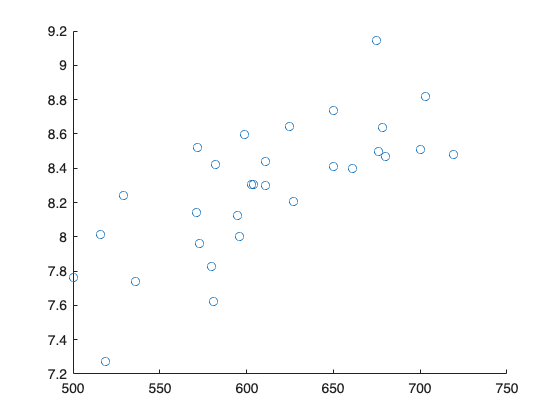

scatter(hitting.R, hitting.hpg)

This was sort of up and to the right, but not clearly connected.  Let's try the next statistic.

## Walks (BB = Bases on Balls) Per Game

 A team that walks more should score more runs.  First we define wpg (walks per game)


$$\mathrm{wpg}=\frac{\mathrm{BB}}{G}$$


hitting.wpg = hitting.BB ./ hitting.G;

### Correlating wpg to Runs and creating a scatter diagram

corrcoef([hitting.wpg hitting.R])

ans =     1.0000    0.6697
    0.6697    1.0000


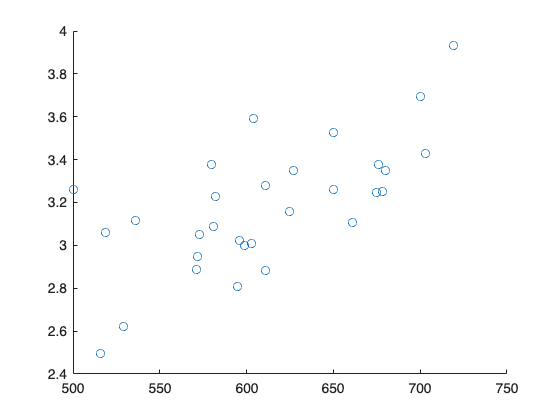

scatter(hitting.R, hitting.wpg)

The a correlation but not as good as the one for hits.

## Strikeouts (SO) per game (kpg)

The team that strikes out less should score more runs.


$$\mathrm{kpg}=\frac{\mathrm{SO}}{G}$$


hitting.kpg = hitting.SO ./ hitting.G;

### Correleating KPG to Runs

We should see a negative correlation between strikeouts per game and runs.

corrcoef([hitting.kpg, hitting.R])

ans =     1.0000   -0.0612
   -0.0612    1.0000


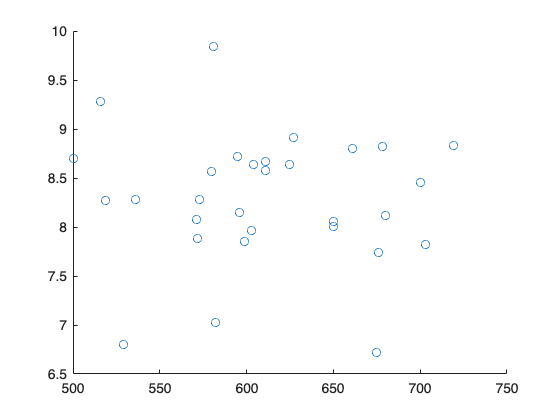

scatter(hitting.R, hitting.kpg)

Wow. There is pretty much no correlation at all.

## Comparing the statistics to each other

Now we'll compare the statistics to see which is best.  First we make a correlation table.

corrcoef([hitting.R hitting.hpg hitting.wpg hitting.kpg])

ans =     1.0000    0.7307    0.6697   -0.0612
    0.7307    1.0000    0.2758   -0.4371
    0.6697    0.2758    1.0000    0.0704
   -0.0612   -0.4371    0.0704    1.0000


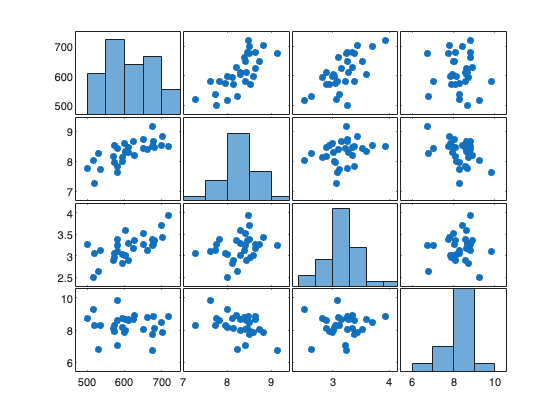

plotmatrix([hitting.R, hitting.hpg, hitting.wpg, hitting.kpg])

In summary, *hits per game* was the best statistic for predicting which team would score more runs.  However, none of these statistics was great.